**List of image filenames**

image_files = {
    'Fig0320(1)(top_left).tif', 
    'Fig0320(2)(2nd_from_top).tif', 
    'Fig0320(3)(third_from_top).tif', 
    'Fig0320(4)(bottom_left).tif'
};

num_images = length(image_files);

**Read the grayscale image**

for idx = 1:num_images
    img = imread(image_files{idx});

**Get image size**

[rows, cols] = size(img);


**Compute the histogram manually**

hist = zeros(1, 256);
for i = 1:rows
    for j = 1:cols
        hist(img(i, j) + 1) = hist(img(i, j) + 1) + 1;
    end
end
    

**Compute the CDF (Cumulative Distribution Function)**

cdf = cumsum(hist);

**Normalize the CDF to range from 0 to 255**

cdf_min = min(cdf(cdf > 0));
cdf_normalized = round((cdf - cdf_min) / (rows * cols - cdf_min) * 255);

**Apply histogram equalization using CDF**

equalized_img = uint8(cdf_normalized(img + 1));

**Compute the histogram of the equalized image manually**

equalized_hist = zeros(1, 256);
for i = 1:rows
    for j = 1:cols
        equalized_hist(equalized_img(i, j) + 1) = equalized_hist(equalized_img(i, j) + 1) + 1;
    end
end

**Plot the results for the current image**

figure('Name', image_files{idx}, 'NumberTitle', 'off');

**Original Image, histogram and CDF of original image**

subplot(2,3,1), imshow(img), title('Original Image');
subplot(2,3,2), bar(0:255, hist), title('Original Histogram');
xlim([0 255]);
subplot(2,3,3), plot(0:255, cdf / (rows * cols)), title('CDF');
xlim([0 255]);
    

**Equalized Image, histogram and CDF of equalised image**

subplot(2,3,4), imshow(equalized_img), title('Equalized Image');
subplot(2,3,5), bar(0:255, equalized_hist), title('Equalized Histogram');
xlim([0 255]);
subplot(2,3,6), plot(0:255, cdf_normalized / 255), title('CDF');
xlim([0 255]);

**Apply inbuilt histeq() function for verification**

img_histeq = histeq(img);

**Compute inbuilt histogram, CDF and MSE for verification**

histeq_hist = imhist(img_histeq);
histeq_cdf = cumsum(histeq_hist) / (rows * cols);
mse_error = mean((double(equalized_img(:)) - double(img_histeq(:))).^2);

**Plot verification results**

figure('Name', ['Verification - ' image_files{idx}], 'NumberTitle', 'off');

**Inbuilt Equalized Image, histogram and CDF of equalised image**

subplot(2,3,1), imshow(img_histeq), title('Inbuilt Equalized Image');
subplot(2,3,2), bar(0:255, histeq_hist), title('Histogram');
xlim([0 255]);
subplot(2,3,3), plot(0:255, histeq_cdf), title('CDF');
xlim([0 255]);

**Difference between Manual and Inbuilt Images**

diff_img = imabsdiff(equalized_img, img_histeq);
subplot(2,3,4), imshow(diff_img, []), title('Difference Image');

**Difference Histogram**

diff_hist = abs(equalized_hist - histeq_hist');
subplot(2,3,5), bar(0:255, diff_hist), title('Histogram Difference');
xlim([0 255]);

**Print Mean Squared Error**

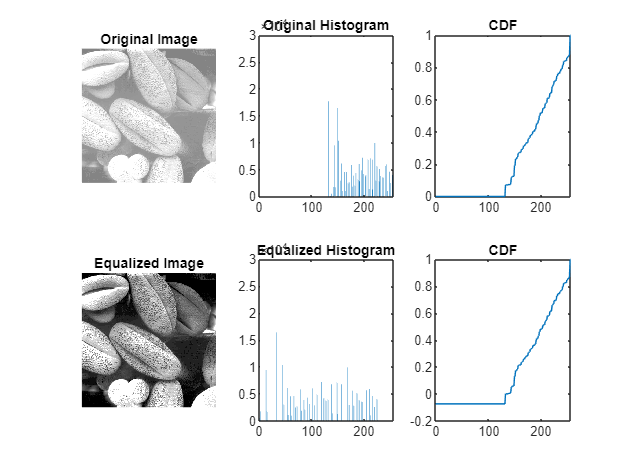

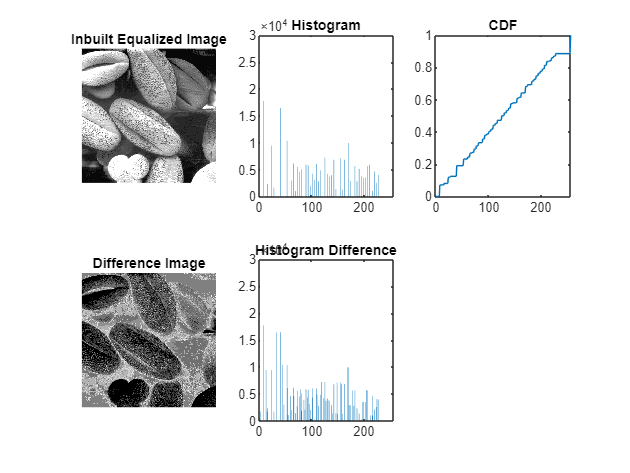

MSE between manual and inbuilt equalized image for Fig0320(1)(top_left).tif: 53.6019


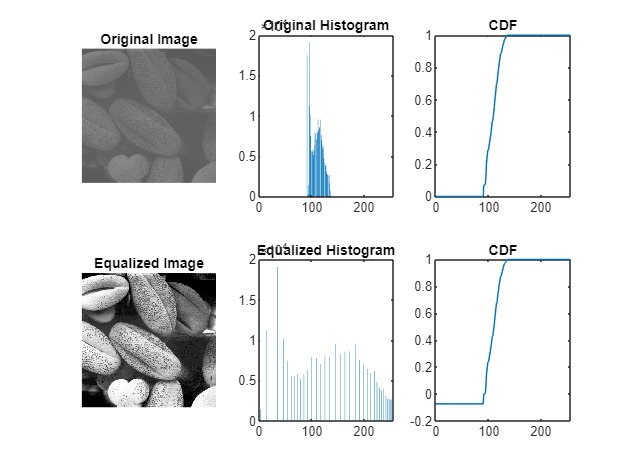

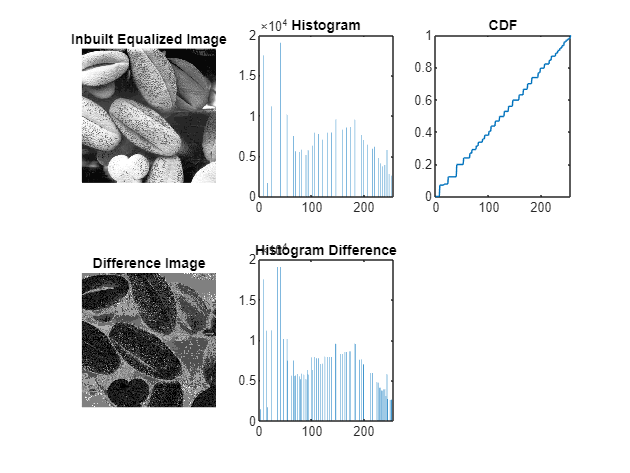

MSE between manual and inbuilt equalized image for Fig0320(2)(2nd_from_top).tif: 33.7266


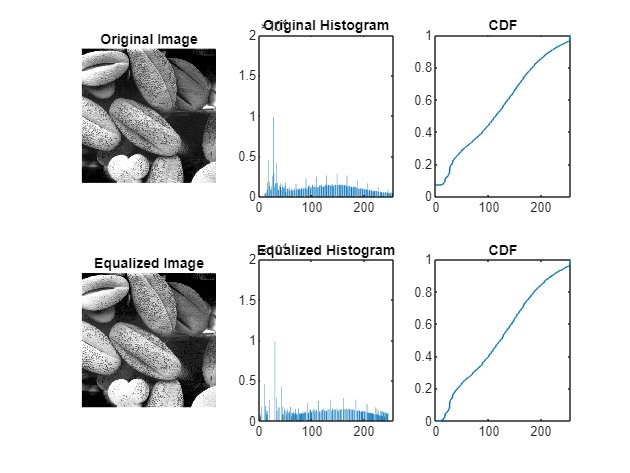

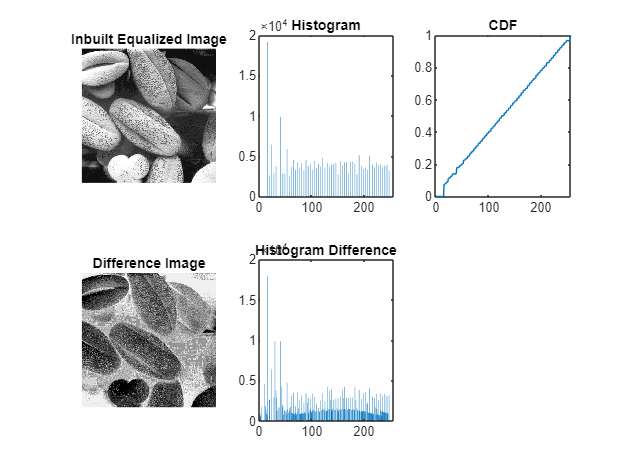

MSE between manual and inbuilt equalized image for Fig0320(3)(third_from_top).tif: 91.5830


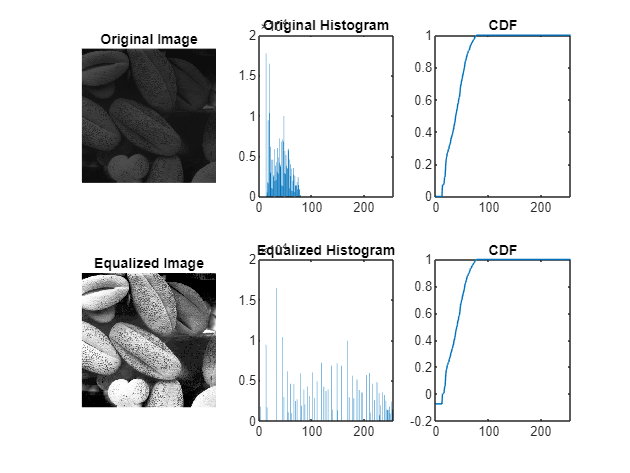

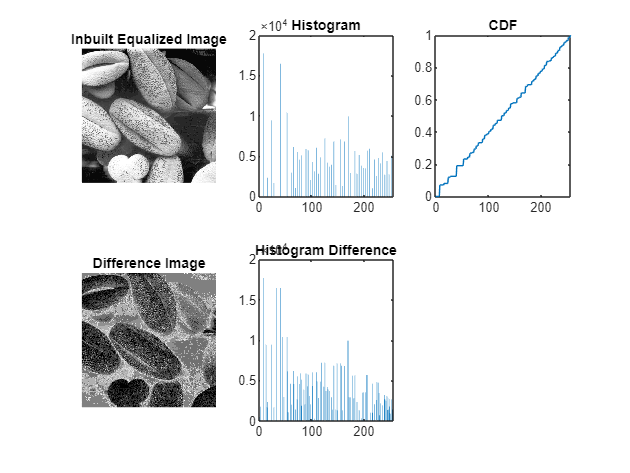

MSE between manual and inbuilt equalized image for Fig0320(4)(bottom_left).tif: 54.1493


fprintf('MSE between manual and inbuilt equalized image for %s: %.4f\n', image_files{idx}, mse_error);
end